Σε αυτό το livenotebook παρουσιάζεται ο τρόπος δημιουργίας ενός απλού FC νευρωνικού δικτύου παρόμοιο με αυτό που είχε δημιουργηθεί στα προηγούμενα μαθήματα.

x = -3:0.1:3;
noise = 0.2*rand(1,size(x,2))

noise =     0.1783    0.0872    0.0152    0.1751    0.1147    0.1921    0.0574    0.1873    0.1856    0.0099    0.1251    0.0120    0.0704    0.1372    0.1582    0.1993    0.0693    0.0433    0.0251    0.0223    0.0251    0.1874    0.1118    0.1837    0.1000    0.0168    0.1723    0.1165    0.0707    0.1249    0.0234    0.1557    0.0944    0.1713    0.0946    0.1391    0.1718    0.1460    0.1030    0.1248    0.1079    0.0205    0.0522    0.0335    0.0363    0.0134    0.1908    0.1471    0.1311    0.1622


y = x.^2 - 3*x  +2 + noise;
y(1,12) = y(1,12) +4 ;
y(1,30) = y(1,30) -4;

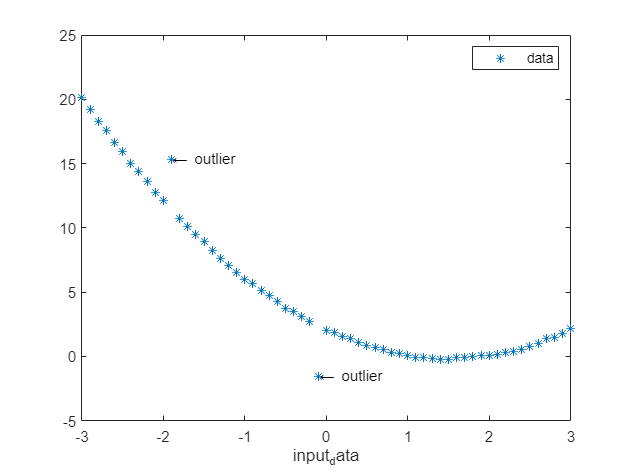

figure
plot(x,y(1,:), '*')

txt = '\leftarrow outlier';
text(x(1,12),y(1,12),txt)

txt2 = '\leftarrow outlier';
text(x(1,30),y(1,30),txt2)

legend('data')
xlabel('input_data')

% Split the data to training, validation and testing.
indexes = randperm(size(x,2)) % to get

indexes =     13    61    21     8    16    33    26    14    41     5    18     2    28    42     3    25    17    34    37    31    49    23    53    24    35    38    39    40    56    36     9    55    59    51    57    54    29    22    10    44    15    52    32    43     7    19    12    46    11    48


i_train = floor(size(x,2)/10*8)

i_train = 48

i_val = floor(size(x,2)/10*9) 

i_val = 54


x_train = x(1,indexes(1:i_train));
x_val = x(1,indexes(i_train:i_val));
x_test = x(1,indexes(i_val:end));

y_train = y(1,indexes(1:i_train));
y_val = y(1,indexes(i_train:i_val));
y_test = y(1,indexes(i_val:end));

Δημιουργία νευρωνικού: Φτιάχνουμε ένα διάνυσμα/λίστα με τα επιθυμητά **στρώματα/layers**. **Προσοχή, **όταν χρησιμοποιούμε την συνάρτηση **trainNetwork** για την εκπαίδευση του δικτύου, όπως παρακάτω, τότε το τελευταίο **στρώμα/layer** πρέπει να είναι το **regressionLayer** για προβλήματα **παλινδρόμησης**. Παρακάτω δημιουργείται ένα νευρωνικό δίκτυο παρόμοιο με αυτό του fitnet. **Σημείωση: **Οι **συναρτήσεις** **ενεργοποίησης/activation functions** αποτελούν και αυτές στρώματα/layers.

layers = [
    featureInputLayer(1)
    fullyConnectedLayer(10)
    tanhLayer
    fullyConnectedLayer(1)
    regressionLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Feature Input       1 features
     2   ''   Fully Connected     10 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     1 fully connected layer
     5   ''   Regression Output   mean-squared-error

Για να μπορέσουμε να δούμε το δίκτυο μας μπορούμε να χρησιμοποιήσουμε την εντολή layerGraph για να δημιουργήσουμε ένα γράφο και στη συνέχεια με την εντολή plot να τον εμφανίσουμε. Ειδάλλως υπάρχει και η επιλογή

lgraph = layerGraph(layers)

lgraph =   LayerGraph with properties:

         Layers: [5×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


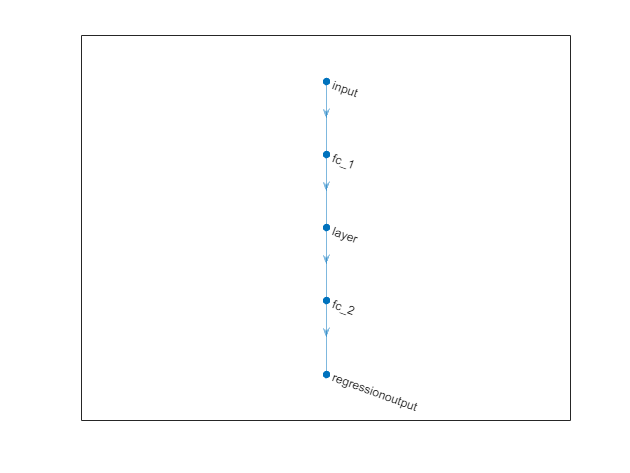

figure
plot(lgraph)

Αν κάποιος θέλει να δημιουργήσει γραφικά το δίκτυο μπορεί να ανοίξει την εφαρμογή/add on της Matlab `deepNetworkDesigner ``είτε από το πρόγραμμα είτε εκτελώντας το παρακάτω κελί.`

deepNetworkDesigner

Πριν ξεκινήσουμε την διαδικασία εκπαίδευσης πρέπει να ορίσουμε τις παραμέτρους της. Το Matlab μας δίνει τη δυνατότητα να ορίσουμε μερικά ορίσματα στην συνάρτηση trainingOptions όπως είναι:

- το πρώτο όρισμα είναι ο **βελτιστοποιητής**/**optimizer** με επιλογές** 'sgdm', 'rmsprop', 'adam'**

- το δευτερό αποτελεί το αν τα δεδομένα **εκπαίδευσης/training **θα ανακατεύονται και κάθε πότε.

- το τρίτο είναι ο αριθμός δειγμάτων ανα batch. Όπως αναφέρθηκε στο μάθημα οι λόγοι που χρησιμοποιούμε **batchsize** αντί για όλο τα δεδομένα εκπαίδευσης ταυτόχρονα είναι πρώτον ο περιορισμός της μέγιστης δυνατής μνήμης και δεύτερον ο απαιτούμενος χρόνος σύγκλισης.

- το τέταρτο όρισμα είναι ο μέγιστος αριθμός **εποχών/epcohs**. Αν δίναμε και κρητίριο πρόωρουεποχή όπως είναι το εποχή τότε μπορεί να μην φτάναμε στο μέγιστο αριθμό **εποχών**. Ως μία **εποχή ορίζεται το πλήρες πέρασμα όλων των δεδομένων εκπαίδευσης από τον αλγόριθμο μάθησης ενώ ως επανάληψη/Iteration ορίζεται η μία ανανέωση βαρών ή αλλίως το πέρασμα ένα mini batch ή απλώς batch.**

- το πέμπτο όρισμα είναι ο αρχικό ρυθμός μάθησης που αφορά το πόσο μεγάλα θα είναι τα βήματα της ανανέωσης παραμέτρων προς την κατεύθυνση που δείχνει η παράγωγος της συναρτήσης κόστους ως προς την παράμετρο. Συνήθως διαλέγεται μία τιμή μεταξύ του 1e-4 - 1e-3 αλλά μπορεί να είναι και πιο μικρή αν δούμε πως το νευρωνικό μας δεν συγκλίνει ή πιο μεγάλη αν η εκπαίδευση αργή να συγκλίνει πάρα πολύ και δεν έχουμε μεγάλες αλλαγές/μεγάλεις μειώσεις στις τιμές της συνάρτησης κόστους.

- το έκτο είναι το δεδομένα επικύρωσης/validation data που αποτελούν τα δεδομένα στα οποία θα συγκρίνουμε την ακρίβεια του μοντέλου αν κάποσες **επαναλήψεις(όχι εποχές)**. **ΠΡΟΣΟΧΗ,** τα δεδομένα επικύρωσης δεν πρέπει να συγχαίονται με τα ελέγχου/test data καθώς τα δεύτερα χρησιμοποιούνται μόνο όταν το μοντέλο μας έχει εκπαιδευτεί πλήρως και είμαστε έτοιμοι να το χρησιμοποιήσουμε στον πραγματικό κόσμο.

- το έκτο είναι η συχνότητα επικύρωσης δηλαδή κάθε πόσες επαναλήψεις θα δοκιμάζουμε το μοντέλο ας στα validation data.

- το έβδομο είναι η "υπομονή"/validation patience, δηλαδή πόσες φορές επιτρέπουμε το σφάλμα στα validation data να μην μειωθεί. Αν περάσει αυτό το όριο τότε η διαδικασία εκπαίδευσης διακόπτεται ακόμη και αν ο μέγιστος αριθμός εποχών δεν έχει επιτευχθεί.

- το τελευταία ορίσματα έχουν να κάνουμε με το τι θέλουμε να εμφανίζεται κατά τη διαδικασία εκπαίδευσης.

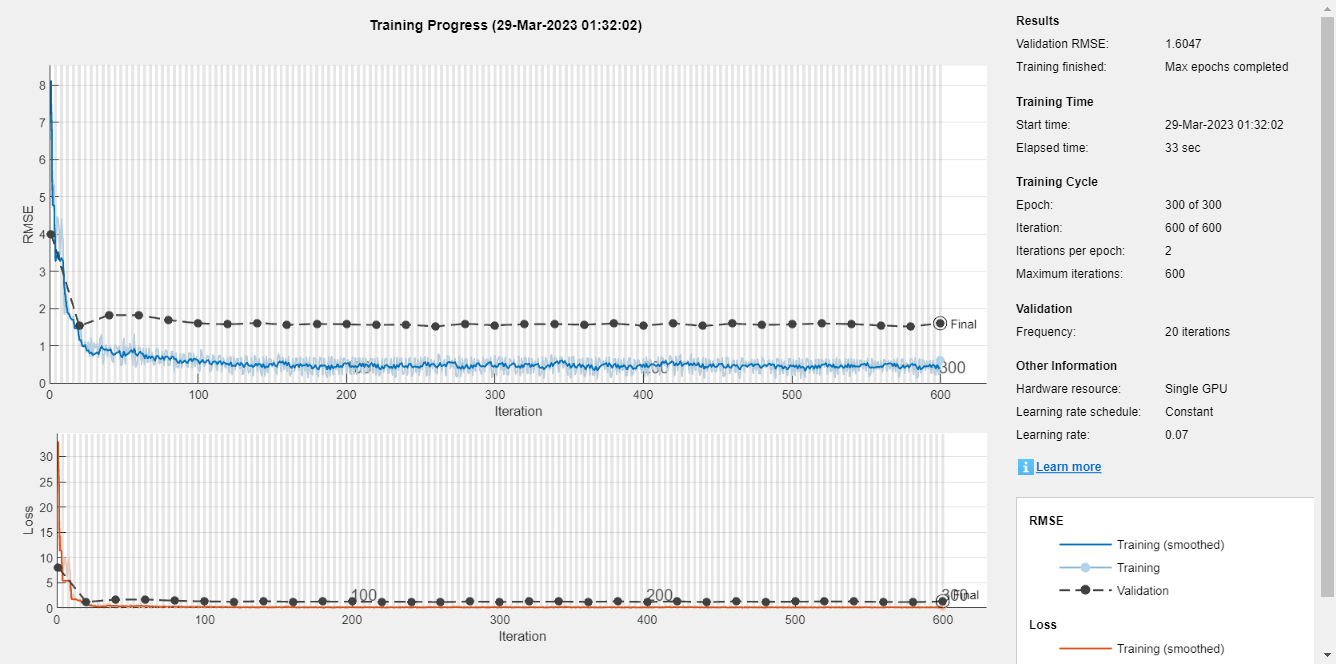

options = trainingOptions('sgdm',...

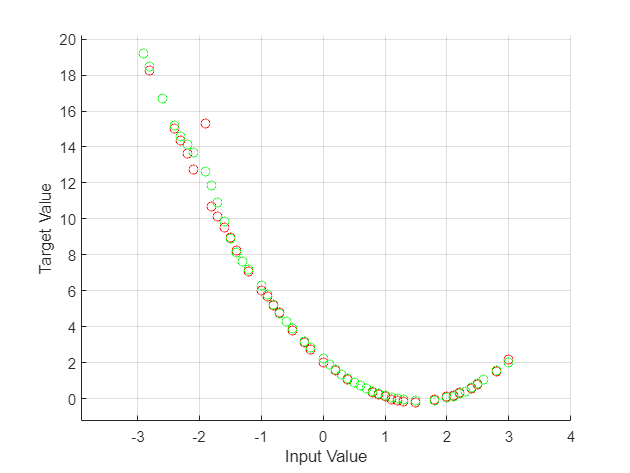

    'Shuffle','every-epoch',...
    'MiniBatchSize',24, ...

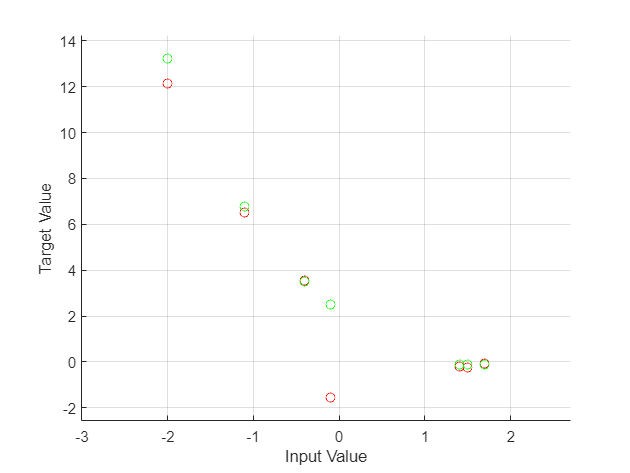

    'MaxEpochs',300, ...
    'InitialLearnRate',7e-2, ...

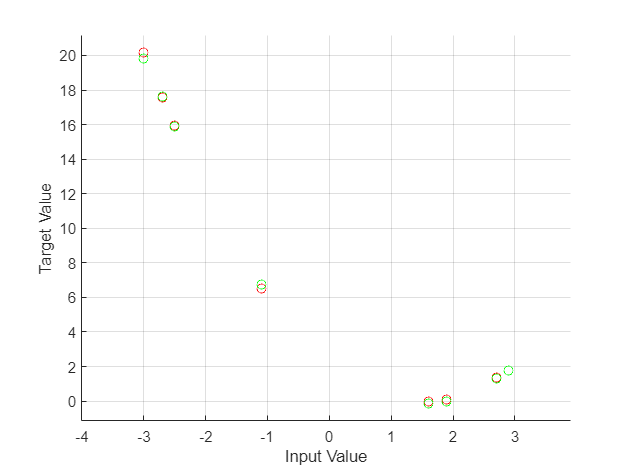

    'ValidationData',{x_val', y_val'},....
    'ValidationFrequency',20, ...

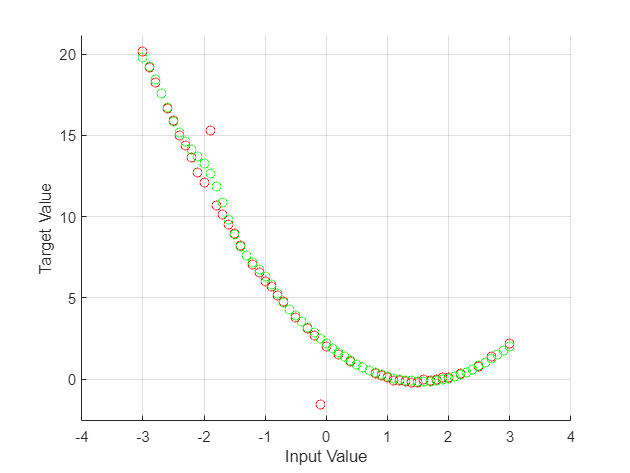

    'ValidationPatience', 20,...
    'Plots','training-progress', ...

    'Verbose',false);

net = trainNetwork(x_train',y_train',layers,options);

pred_and_plot(x_train,y_train,net)

pred_and_plot(x_val,y_val,net)

pred_and_plot(x_test,y_test,net)

pred_and_plot(x,y,net)

data = get_housing_data();

Ως εξασκηση δοκιμάστε τα παρακάτω:

- Αλλάξτε τον **βελτιστοποιητή**/**optimizer** σε **adam** και σχολιάστε το **τι** **παρατηρείτε**

- Δοκιμάστε **πιο μικρές τιμές** του **InitialLearnRate** σε συνδυασμό με μεγαλύτερες και μικρότερες τιμές του μέγιστου αριθμού **εποχών**.

- Δοκιμάστε να χρησιμοποιησετε τα δεδομένα του αρχείου **Housing csv** για να εκπαιδεύσετε ένα παρόμοιο δίκτυο για το οποίο θα έχετε ως είσοδο τα **τετραγωνικά(area)** του σπιτιού και σαν έξοδο την **τιμή(price)**. Τα δεδομένα μπορείτε να τα εισαγάγετε μέσω της συνάρτησης get_housing_data που σας γυρνάει ένα table με τα δεδομένα αρκεία να έχετε το αρχείο **Housing.csv** στον **ίδιο** φάκελο με το αρχείο custom_net.mlx.

function [] = pred_and_plot(x,y,net)
    preds = predict(net,x');
    figure
    scatter(x,y, 'r')
    hold on
    hold on
    scatter(x,preds, 'g')
    xlabel("Ιnput Value")
    ylabel("Target Value")
    xlim([min(x)-1, max(x)+1])
    ylim([min([y,preds'])-1, max([y,preds'])+1])
    grid on
    

end

function [housing_data] = get_housing_data()

opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["price", "area", "bedrooms", "bathrooms", "stories", "mainroad", "guestroom", "basement", "hotwaterheating", "airconditioning", "parking", "prefarea", "furnishingstatus"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "categorical", "categorical", "categorical", "categorical", "categorical", "double", "categorical", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["mainroad", "guestroom", "basement", "hotwaterheating", "airconditioning", "prefarea", "furnishingstatus"], "EmptyFieldRule", "auto");

% Import the data
housing_data = readtable("Housing.csv", opts);


end